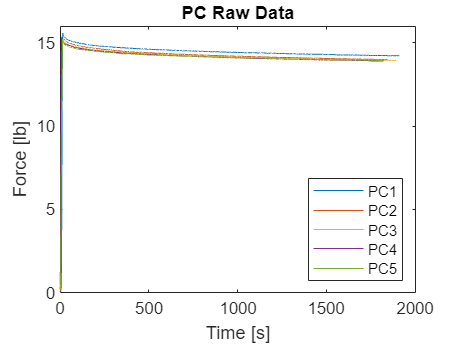

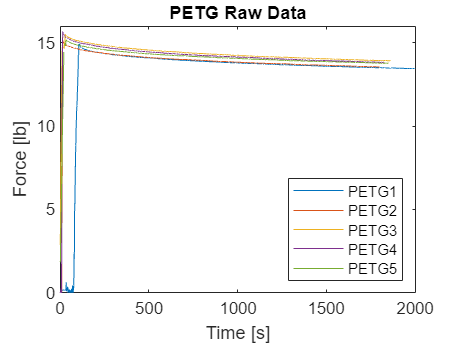

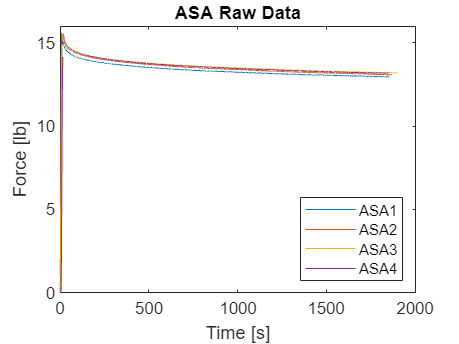

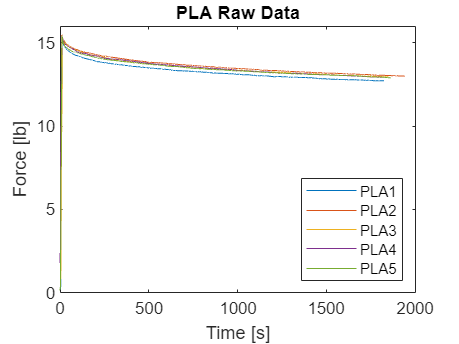

%raw plots
clear
names={'PC','PETG','ASA','PLA'};
YS=[58 46 40 57.4  ];
for h=1:length(names)
    legend_matrix={};
    figure(h)
    for i=1:100
        name=['.\Data\' names{h} num2str(i) '.csv'];
        if isfile(name) == false
            break
        end
        d=readtable(name);
        plot(d.Var1,d.Var2)
        hold on
        legend_matrix{i}=[names{h} num2str(i)];
    end
    title([names{h} ' Raw Data'])
    xlim([0,2000])
    ylim([0 16])
    xlabel('Time [s]')
    ylabel('Force [lb]')
    legend(legend_matrix,'Location','southeast')
    hold off
end

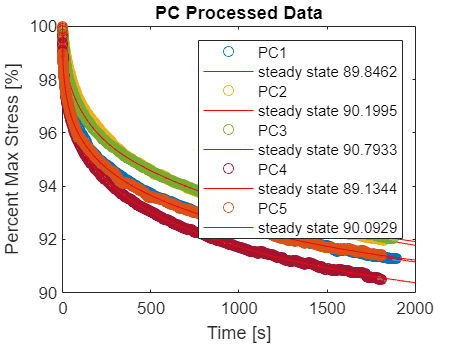

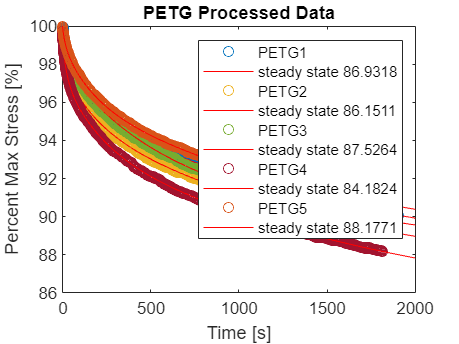

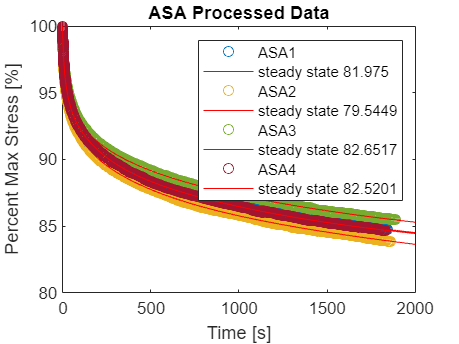

%process
clearvars -except names YS

for y=1:length(names)
    figure(y)
    legend_matrix={};
    for z=1:100
        name=['.\Data\' names{y} num2str(z) '.csv'];
        if isfile(name) == false
            break
        end
        d=readtable(name);
        [maxi,Ind]=max(d.Var2);
        d2.Var2=d.Var2(Ind:end)/maxi*100;
        d2.Var1=d.Var1(Ind:end)-d.Var1(Ind);
        fo = fitoptions('Method','NonlinearLeastSquares','Lower',[0,-0.01,0,-0.1,0,-1,0,-10,0,-100,0,-1000],'StartPoint',[5,-0.001,3,-0.01,1,-0.1,0.1,-1,0.001,-10,0.0001,-100],'Upper',[15,0,6,0,7,0,4,0,3,0,2,0],'MaxIter',100000);
        ft = fittype('100+a*(exp(b*x)-1)+c*(exp(d*x)-1)+e*(exp(f*x)-1)+g*(exp(h*x)-1)+k*(exp(l*x)-1)+m*(exp(n*x)-1)','options',fo);
        [curve,gof] = fit(d2.Var1,d2.Var2,ft);
        SS(z,y)=100-(curve.a+curve.c+curve.e+curve.g+curve.k+curve.m);
        plot(d2.Var1,d2.Var2,'o')
        hold on
        plot(curve,'r')
        legend_matrix{2*z-1}=[names{y} num2str(z)];
        legend_matrix{2*z}=['steady state ' num2str(SS(z,y))];
    end
    legend(legend_matrix)
    title([names{y} ' Processed Data'])
    xlabel('Time [s]')
    %ylim([80,100])
    xlim([0,2000])
    ylabel('Percent Max Stress [%]')
    hold on
end

SS(SS==0)=nan;
dev=std(SS,'omitnan');
avg=mean(SS,'omitnan');
rank=rankttest(SS,.01);
side={'Material';'Ranking';'Test 1';'Test 2';'Test 3';'Test 4';'Test 5';'Average';'Std Dev'};
temp=[names;num2cell([rank;SS;avg;dev])];
table=[side temp]

table = 9×5 cell array
    {'Material'}    {'PC'     }    {'PETG'   }    {'ASA'    }    {'PLA'    }
    {'Ranking' }    {[      1]}    {[      2]}    {[      3]}    {[      4]}
    {'Test 1'  }    {[89.8462]}    {[86.9318]}    {[81.9750]}    {[78.5964]}
    {'Test 2'  }    {[90.1995]}    {[86.1511]}    {[79.5449]}    {[80.1240]}
    {'Test 3'  }    {[90.7933]}    {[87.5264]}    {[82.6517]}    {[82.3578]}
    {'Test 4'  }    {[89.1344]}    {[84.1824]}    {[82.5201]}    {[81.1163]}
    {'Test 5'  }    {[90.0929]}    {[88.1771]}    {[    NaN]}    {[80.4347]}
    {'Average' }    {[90.0133]}    {[86.5938]}    {[81.6729]}    {[80.5259]}
    {'Std Dev' }    {[ 0.6020]}    {[ 1.5413]}    {[ 1.4486]}    {[ 1.3782]}


figure(y+1)
temp=rank;
PYS=15/2.2/(1.75^2/4*pi)./YS*100;
for z=1:length(names)
    scatter(YS(z),avg(z),'filled','o')
    [~,Ind]=max(temp);
    temp(Ind)=0;
    namerank{length(names)+1-z}=names{Ind};
    hold on
end

In order of rank

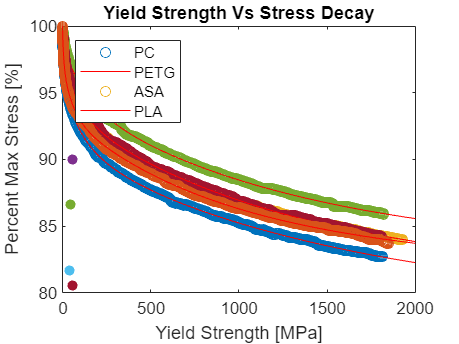

hold off
legend(names,'Location','northwest')
title('Yield Strength Vs Stress Decay')
xlabel('Yield Strength [MPa]')
ylabel('Percent Max Stress [%]')